% Experiment 3

load("Experiment 3/Iin.mat")
load("Experiment 3/Iout.mat")
load("Experiment 3/Vin.mat")
load("Experiment 3/Vout.mat")

Iout1 = Iout(1, :);
Iout2 = Iout(2,:); 
Iout3 = Iout(3,:);

[first, last, mmax_ro_1, bmax_ro_1, Nmax]=linefit(Vout(50:90), Iout1(50:90), 5e-1);
[first, last, mmax_ro_2, bmax_ro_2, Nmax]=linefit(Vout(50:90), Iout2(50:90), 5e-2);
[first, last, mmax_ro_3, bmax_ro_3, Nmax]=linefit(Vout(100:end), Iout3(50:end), 5e-1)

first = 1

last = 162

mmax_ro_3 = 1.5633e-06

bmax_ro_3 = 9.4070e-05

Nmax = 162


[first, last, mmax_ron_1, bmax_ron_1, Nmax]=linefit(Vout(1:11), Iout1(1:11), 5e-4);
[first, last, mmax_ron_2, bmax_ron_2, Nmax]=linefit(Vout(1:11), Iout2(1:11), 5e-3);
[first, last, mmax_ron_3, bmax_ron_3, Nmax]=linefit(Vout(1:11), Iout3(1:11), 5e-4);

bmax_ro_1/mmax_ro_1

ans = 38.0776

bmax_ro_2/mmax_ro_2

ans = 43.4472

bmax_ro_3/mmax_ro_3

ans = 60.1729


ro_1 = 1/mmax_ro_1

ro_1 = 4.0085e+08

ro_2 = 1/mmax_ro_2

ro_2 = 4.5788e+07

ro_3 = 1/mmax_ro_3

ro_3 = 6.3966e+05


ron_1 = 1/mmax_ron_1

ron_1 = 3.7076e+05

ron_2 = 1/mmax_ron_2

ron_2 = 4.1826e+04

ron_3 = 1/mmax_ron_3

ron_3 = 2.1127e+03

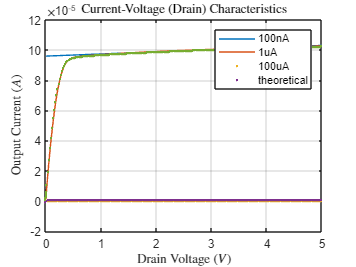



semilogy(Vout, Iout1, '.')
hold on 
semilogy(Vout, Iout2, '.')
semilogy(Vout, Iout3, '.')
legend('100nA', '1uA', '100uA', "theoretical")
title("Current-Voltage (Drain) Characteristics", "Interpreter", "latex")
xlabel("Drain Voltage ($V$)", "Interpreter", "latex")
ylabel("Output Current ($A$)", "Interpreter", "latex")
grid on
hold off



ig_1= ro_1/ron_1

ig_1 = 1.0812e+03

ig_2= ro_2/ron_2

ig_2 = 1.0947e+03

ig_3= ro_3/ron_3

ig_3 = 302.7724

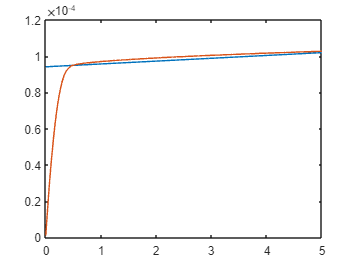


plot(Vout, Vout*mmax_ro_3 + bmax_ro_3)
hold on
plot(Vout, Iout3)